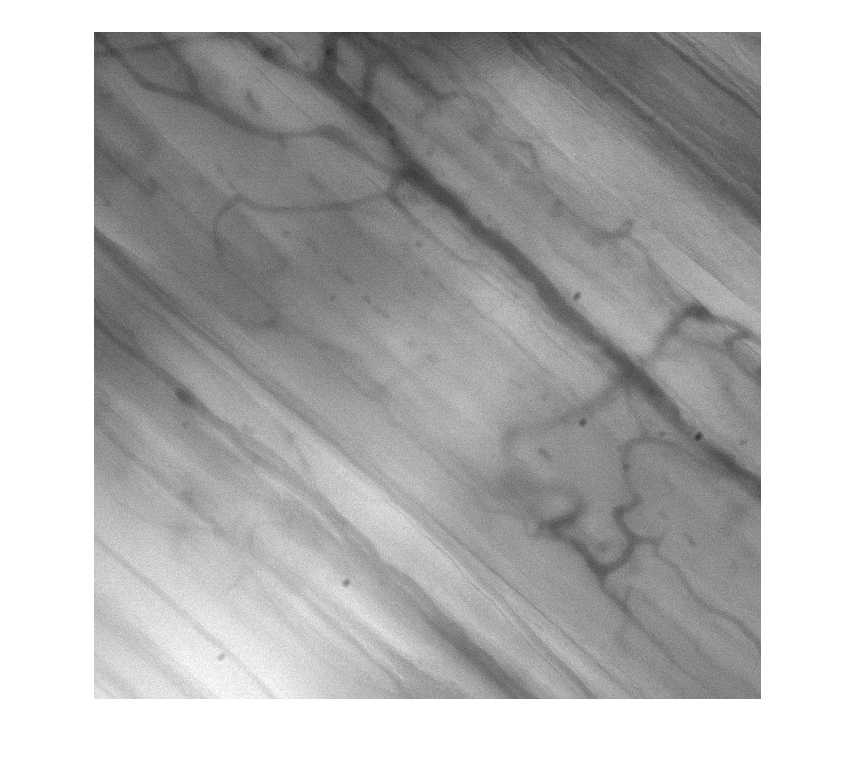

clear all
clc
% get image file names
imgFiles = dir('D:\4970E\*.tiff');
[N, C]= size(imgFiles);
 
 
% get the image size
img = im2double(imread([imgFiles(1).name]));
figure(1);
imshow(img);

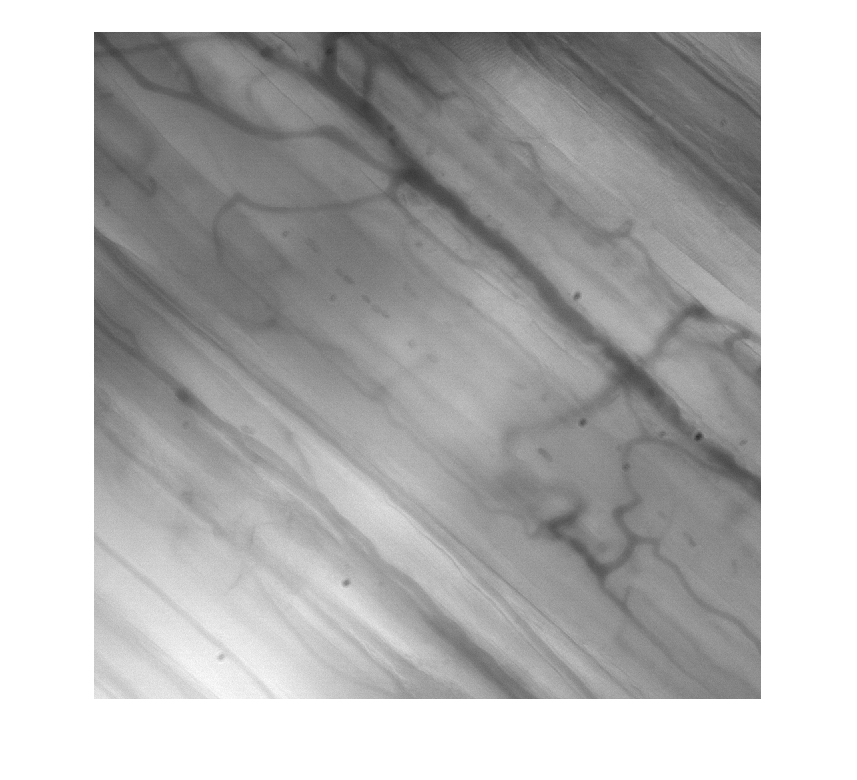

 
img = img / N;
% calculate the average
for m = 2:N
    img = img + im2double(imread([imgFiles(m).name])) / N;
end
figure(2);
imshow(img);

imwrite(img,'TEST.tiff','tiff');


